# Principal Component Analysis (PCA)

Lorem Ipsum

clc
clear
close all

Genero distribuzione normale di $n$ punti random con deviazione standard $\sigma$ e media $\mu$

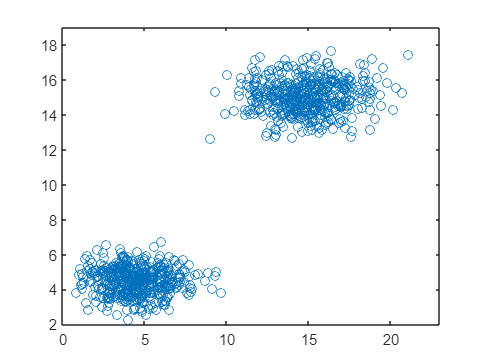

n = 500;                % numero di punti
sigma = [2 0.9];        % deviazione standard su x e su y
mu = 15;                % media

% genero primo set di dati (l = 0)
data = sigma.*randn(n,2) + mu;
l = repelem(0,n,1);

% concateno secondo set di dati (l = 1)
data = [data; (sigma*0.8).*randn(n,2) + mu*0.3];
l = [l; repelem(1,n,1)];
x = data(:,1);
y = data(:,2);

% rappresento dati
% hist(x)
% hist(y)

plot(x,y,'o')
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)

Per filtrare le x e le y appartenenti alla prima distribuzione mi basta usare la sintassi `x(l==0)` e `y(l==0)` che sta per "prendimi le righe che rispettano la condizione `l==0`". Procedo quindi a rappresentare queste due distribuzioni

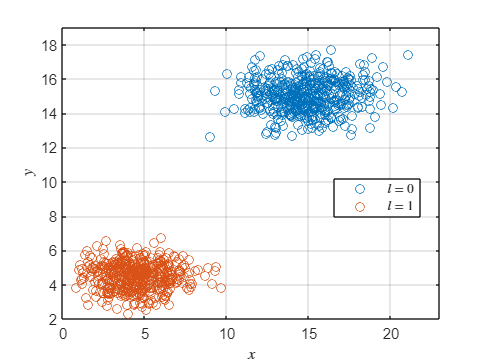

% rappresento la prima distribuzione
plot(x(l==0),y(l==0),'o')
hold on
% rappresento la seconda distribuzione
plot(x(l==1),y(l==1),'o')
hold off
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex','Location','best')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')

% calcolo media
% xm = mean(x);
% ym = mean(y);

% centro i dati
% xc = x-xm;
% yc = y-ym;

% plotto distribuzione centrata
% plot(xc(l==0),yc(l==0),'o')
% hold on
% plot(xc(l==1),yc(l==1),'o')
% hold off
% xlim([floor(min(xc))-1 ceil(max(xc))]+1)
% ylim([floor(min(yc))-1 ceil(max(yc))]+1)
% grid on
% legend("$l = 0$","$l = 1$",'Interpreter','latex','Location','best')
% xlabel("$x$",'Interpreter','latex')
% ylabel("$y$",'Interpreter','latex')
% title("Distribuzioni centrate nell'origine")

Adesso applichiamo una trasformazinoe lineare alle distribuzioni dei dati. Se la matrice della trasformazione $T$ è


$$T=\pmatrix{1 & 1 \cr -1 & 1}$$


e il dataset contiene gli $n$ punti $P$


$$P=\pmatrix{x_1 & y_1 \cr x_2 & y_2 \cr ... & ... \cr  x_n & y_n}$$


allora i punti trasformati $P'$ si otterranno eseguendo il prodotto matriciale $T P^T$ dove $P^T$ indica la trasposta di $P$


$$P' =T P^T= \pmatrix{1 & 1 \cr -1 & 1} \pmatrix{x_1 & x_2 & ... & x_n \cr y_1 & y_2 & ... & y_n}$$


% creo matrice trasformazione
linear_trasformation = [1 1; -1 1]

linear_trasformation =      1     1
    -1     1



% applico trasformazione
transformed_data = (linear_trasformation*(data'))'

transformed_data =    35.9452   -5.4436
   29.2648   -0.1362
   31.9673   -0.6371
   29.6368   -0.9509
   28.0531    0.6450
   27.4641    0.7300
   27.8715    1.8958
   31.5756   -2.4742
   28.3844    0.6172
   28.9019    2.7785


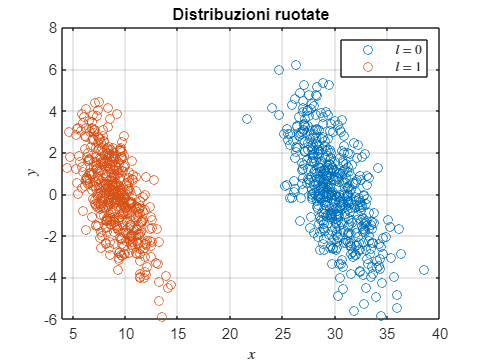


x = transformed_data(:,1);
y = transformed_data(:,2);

% rappresento distribuzioni ruotate
plot(x(l==0),y(l==0),'o')
hold on
plot(x(l==1),y(l==1),'o')
hold off
xlim([floor(min(x))-1 ceil(max(x))]+1)
ylim([floor(min(y))-1 ceil(max(y))]+1)
grid on
legend("$l = 0$","$l = 1$",'Interpreter','latex')
xlabel("$x$",'Interpreter','latex')
ylabel("$y$",'Interpreter','latex')
title("Distribuzioni ruotate")

% esporto in md
livescript2markdown("pca.mlx","../README.md","AddMention",true)

Coverting latex to markdown is complete
README.md
Note: Related images are saved in README_images


ans = "C:\Users\Dennis Angemi\Documents\GitHub\machine-learning-for-physics\2_principal_component_analysis\README.md"